fs = 44100;

tones = [1, 1, 5, 5, 6, 6, 5];
rhythms = [0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 1.0];
scale = 'C'; 
weights_clarinet = [1.0, 0.0, 0.5, 0.0, 0.3, 0.0, 0.1];
weights_string = [1.0, 0.5, 0.33, 0.25, 0.2, 0.16, 0.14];
weights_organ = [1.0, 0.2, 0.8, 0.1, 0.5, 0.1, 0.0];

fprintf('1. 正在播放风格1\n');

1. 正在播放风格1


music_A = gen_music_poly(tones, scale, rhythms, fs, weights_clarinet);
sound(music_A, fs);
audiowrite('star_clarinet.wav', music_A, fs);
pause(4);

fprintf('正在播放风格2\n');

正在播放风格2


music_B = gen_music_poly(tones, scale, rhythms, fs, weights_string);
sound(music_B, fs);
audiowrite('star_string.wav', music_B, fs);
pause(4);


fprintf('正在播放风格3\n');

正在播放风格3


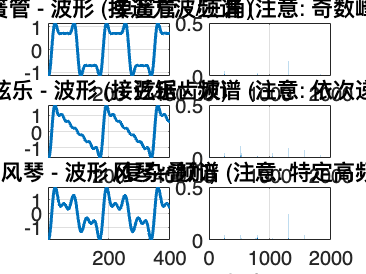

music_C = gen_music_poly(tones, scale, rhythms, fs, weights_organ);
sound(music_C, fs);
audiowrite('star_organ.wav', music_C, fs);
pause(4);

% 取第一个音符 (Do, 261Hz) 进行微观分析
duration = 0.5;
t = linspace(0, duration, round(duration*fs));
f_base = 261.63; 
wave_A = gen_note_poly(f_base, t, weights_clarinet);
wave_B = gen_note_poly(f_base, t, weights_string);
wave_C = gen_note_poly(f_base, t, weights_organ);

figure('Color', 'w', 'Name', 'Timbre Analysis');
sample_range = 1000:1400; 

subplot(3,2,1); plot(wave_A(sample_range), 'LineWidth',1.5); title('单簧管 - 波形 (接近方波/三角)'); grid on; axis tight;
subplot(3,2,3); plot(wave_B(sample_range), 'LineWidth',1.5); title('弦乐 - 波形 (接近锯齿波)'); grid on; axis tight;
subplot(3,2,5); plot(wave_C(sample_range), 'LineWidth',1.5); title('风琴 - 波形 (复杂叠加)'); grid on; axis tight;

L = length(t);
f_axis = fs*(0:(L/2))/L; 
Y_A = fft(wave_A); P_A = abs(Y_A/L); P_A = P_A(1:L/2+1);
Y_B = fft(wave_B); P_B = abs(Y_B/L); P_B = P_B(1:L/2+1);
Y_C = fft(wave_C); P_C = abs(Y_C/L); P_C = P_C(1:L/2+1);

freq_limit = 2000; 
idx_limit = find(f_axis > freq_limit, 1);

subplot(3,2,2); bar(f_axis(1:idx_limit), P_A(1:idx_limit)); 
title('单簧管 - 频谱 (注意: 奇数峰值强)'); xlabel('频率 (Hz)'); grid on;

subplot(3,2,4); bar(f_axis(1:idx_limit), P_B(1:idx_limit)); 
title('弦乐 - 频谱 (注意: 依次递减)'); xlabel('频率 (Hz)'); grid on;

subplot(3,2,6); bar(f_axis(1:idx_limit), P_C(1:idx_limit)); 
title('风琴 - 频谱 (注意: 特定高频突起)'); xlabel('频率 (Hz)'); grid on;

function full_wave = gen_music_poly(tones, scale, rhythms, fs, weights)
    full_wave = [];
    noctave = 0; rising = 0;
    
    for i = 1:length(tones)
        duration = rhythms(i);
        t = linspace(0, duration, round(duration*fs));       
        f0 = tone2freq2(tones(i), scale, noctave, rising);
        
        if tones(i) == 0
            note_wave = zeros(1, length(t));
        else
            note_wave = gen_note_poly(f0, t, weights);
            
            decay = exp(-3 * t / duration);
            note_wave = note_wave .* decay;
        end
        
        full_wave = [full_wave, note_wave];
    end
    
    full_wave = full_wave / max(abs(full_wave)) * 0.9;
end

function wave = gen_note_poly(f0, t, weights)
    wave = zeros(1, length(t));
    
  
    for k = 1:length(weights)
        amplitude = weights(k);
        if amplitude > 0
            wave = wave + amplitude * sin(2 * pi * (k * f0) * t);
        end
    end
end

function freq = tone2freq2(tone, scale, noctave, rising)
    base = 261.63; 
    dic = [0, 2, 4, 5, 7, 9, 11];
    if tone >= 1
        n = dic(tone) + noctave*12 + rising;
        freq = base * (2^(n/12));
    else
        freq = 0;
    end
end